# ADCS Homework 6

Dillon Allen

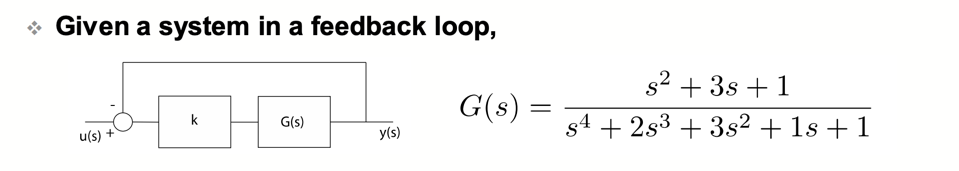

## Problem 1

### Formulate $G(s)$ in Matlab

G = tf([1 3 1], [1 2 3 1 1])

G =
 
         s^2 + 3 s + 1
  ---------------------------
  s^4 + 2 s^3 + 3 s^2 + s + 1
 
Continuous-time transfer function.



## Problem 2

### Draw the Root Locus Plot. 

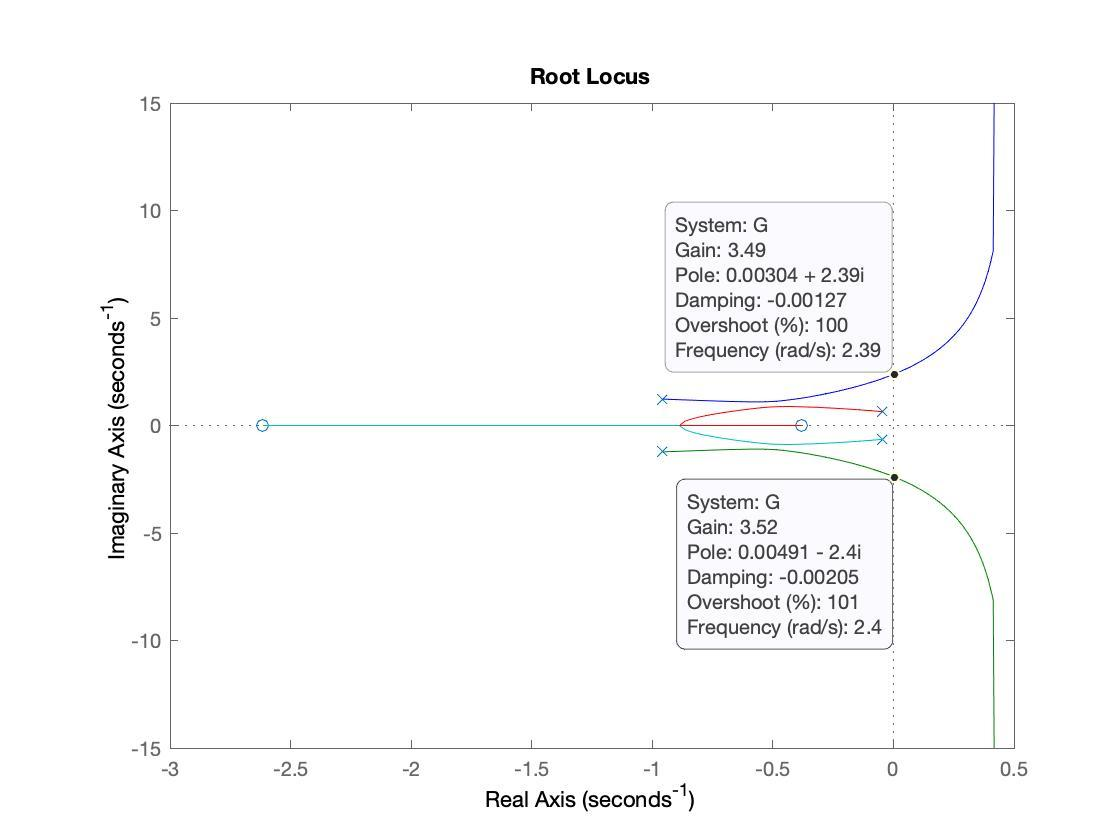

## Problem 3

### At what gain values does the system go unstable?

Now, from this image we can see that the gain is unstable around $\pm 2.4j$. To find a more exact value, we will use rlocfind(G)

rlocfind(G,[0 + 1i*2.4])

ans = 3.5199

rlocfind(G, [0 - 1i*2.4])

ans = 3.5199

Therefore, the gain that leads to instability is

gain = $3.5199$

## Problem 4

### What are the gain and phase margins for the system?

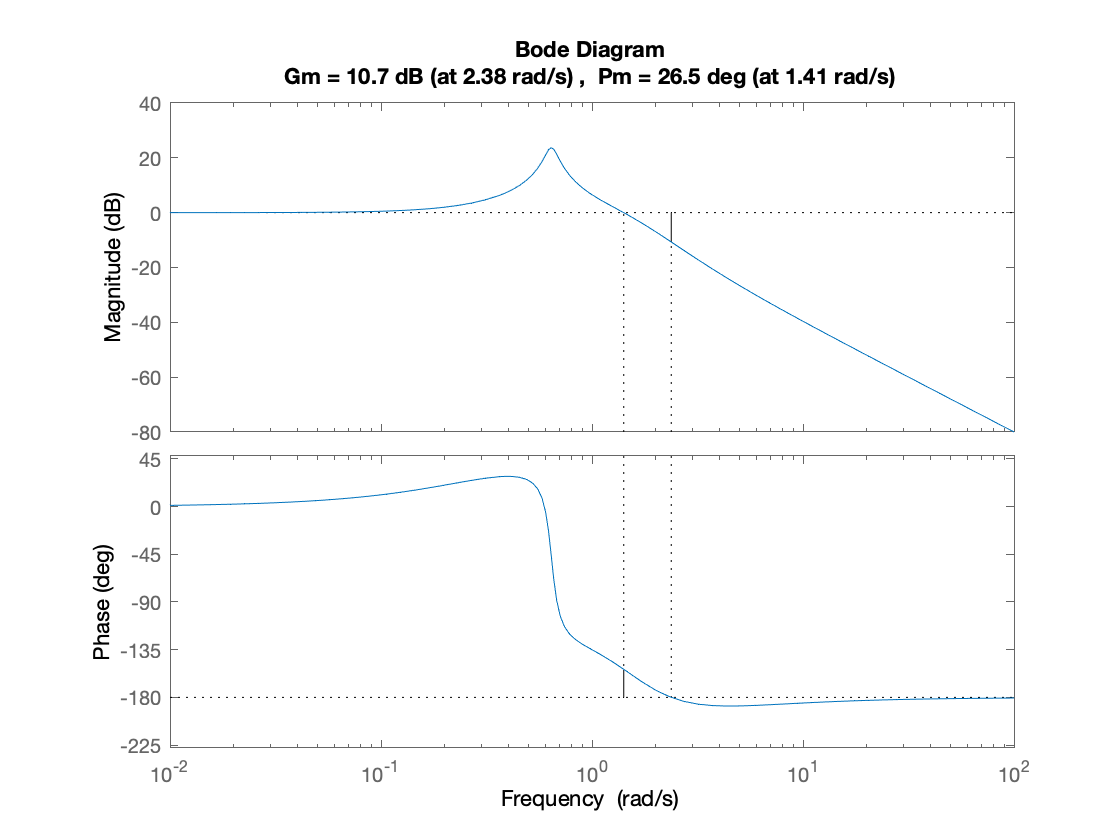

margin(G)

## Problem 5

### Draw the Nichols plot for the system $G(s)$. Annotate the phase and gain margins.

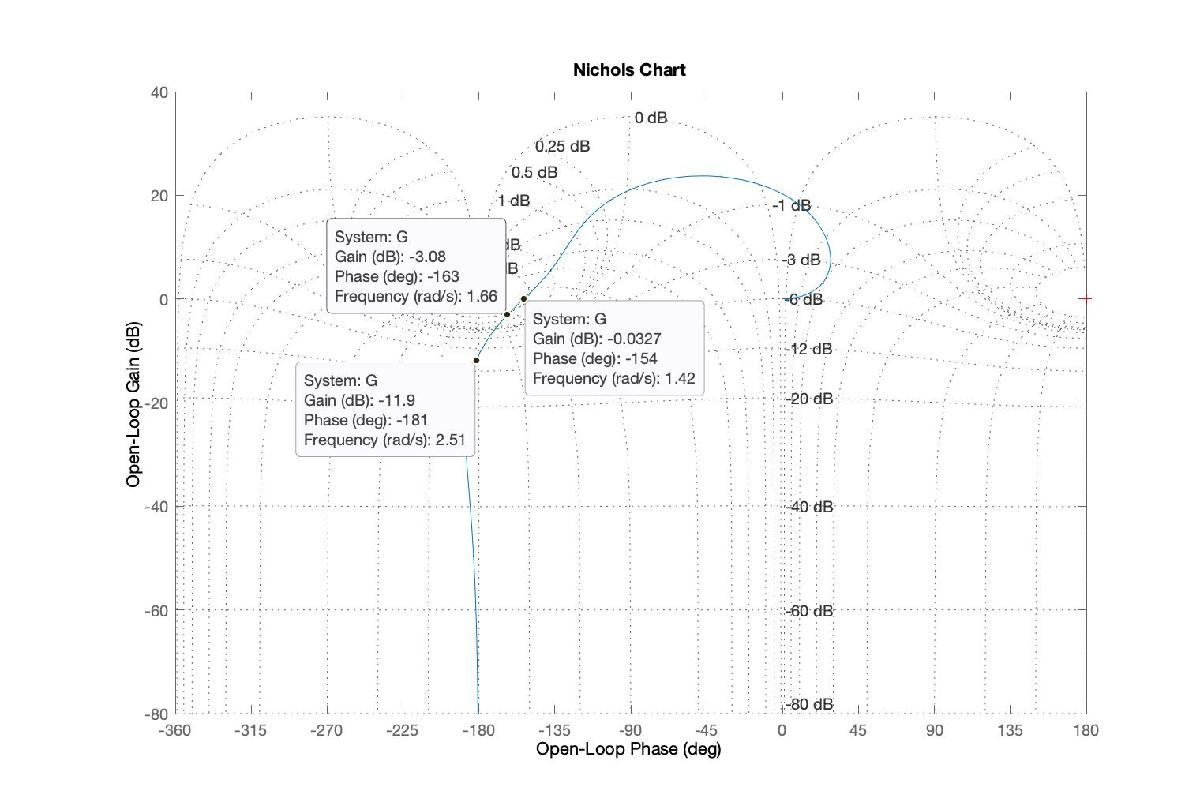

## Problem 6

### For $K = 2$, what is the CLTF, $\frac{Y(s)}{U(s)}$?

From the block layout, the CLTF will be

#### 
$$\frac{Y(s)}{U(s)} = \frac{K(s) G(s)}{1 + K(s)G(s)}$$


#### Using $K = 2$, $G(s) = \frac{s^2 + 3s + 1}{s^4 + 2s^3 + 3s^2 + s + 1}$, we have

#### 
$$\frac{Y(s)}{U(s)} = \frac{2 s^2 + 6s + 2}{s^4 + 2s^3 + 5s^2 + 7s + 2}$$


## Problem 7

### Plot the output of the step function, for $K = 2$.

cltf = tf([2 6 2], [1 2 5 7 2])

cltf =
 
         2 s^2 + 6 s + 2
  -----------------------------
  s^4 + 2 s^3 + 5 s^2 + 7 s + 2
 
Continuous-time transfer function.



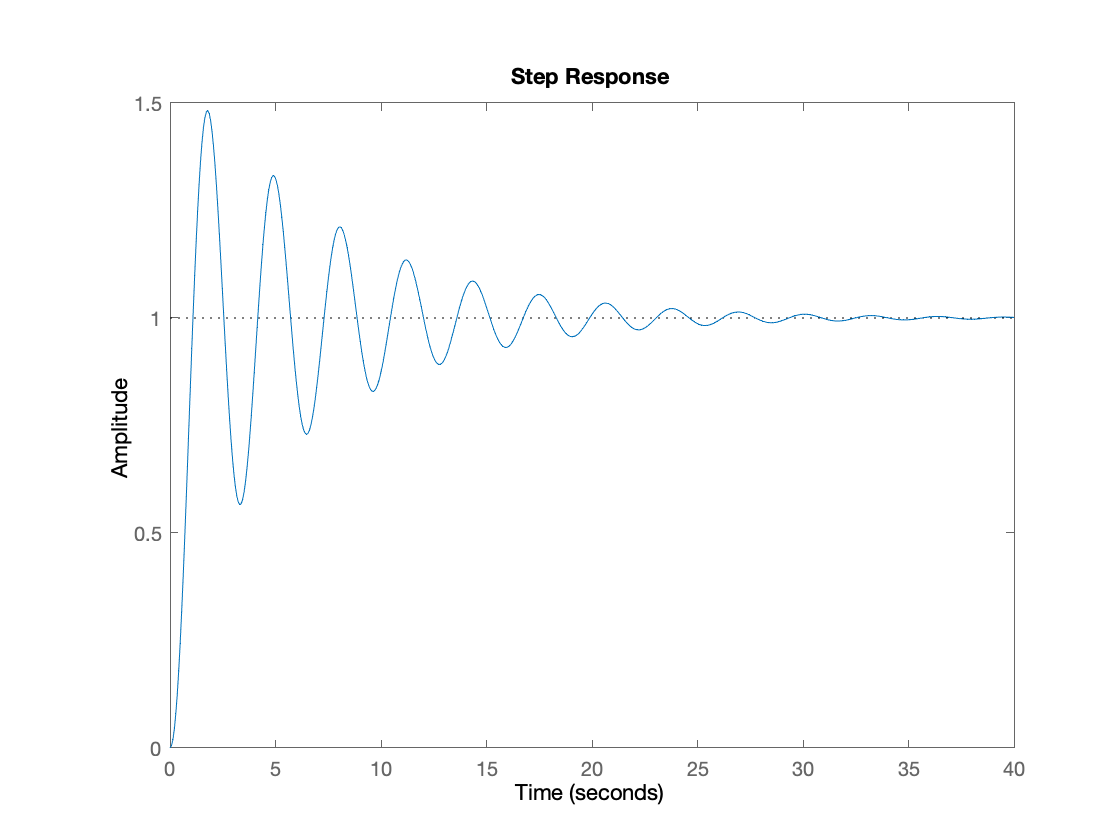

step(cltf)